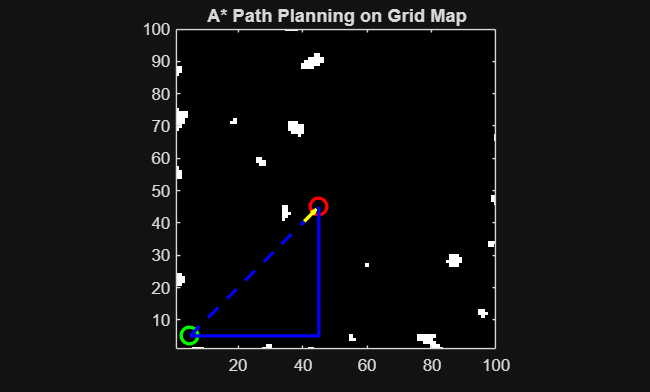

clc; clear; close all; % clear command window, workspace, and figures

mapSize = 100; % define map size
map = zeros(mapSize);  % initialize empty map (all free space) - 0 means free space!

% generate random blob-shaped obstacles (any value >0.6 becomes 1, meaning it's an obstacle)
blob = imgaussfilt(rand(mapSize), 2) > 0.6; 

% place obstacles in the map
map(blob) = 1; 

start = [5,5];
goal = [45,45];

% makes sure that start & end is not blocked
map(start(1), start(2)) = 0;
map(goal(1), goal(2)) = 0;

path = astar(map, start, goal); % compute path using A*

figure;
imagesc(map'); % display map as image
colormap(gray);
axis equal;
hold on; % keep current plot so more points can be added
set(gca,'YDir','normal'); % make y-axis point upward normally

%Sets visible x and y limits of the plot & Keeps the display matched to map size
xlim([1 mapSize]); 
ylim([1 mapSize]);

plot(start(1), start(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(goal(1), goal(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
title('Map with Obstacles');

if ~isempty(path)
    plot(path(:,1), path(:,2), 'b-', 'LineWidth', 2); % plot planned path
else
    disp('No path found.');
end

title('A* Path Planning on Grid Map');

% Vehicle parameters
x = start(1);
y = start(2);
theta = deg2rad(45);  % initial heading
v = 2;  % constant speed
dt = 0.1; % time step
delta = 0.0;  % constant steering angle
L = 2.5;    % wheelbase

trajectory = [];

for t = 0:dt:25
    
    % Update position (no steering yet)
    x = x + v * cos(theta) * dt;
    y = y + v * sin(theta) * dt;
    theta = theta + (v / L) * tan(delta) * dt;
    
    trajectory = [trajectory; x y];
end

% Plot trajectory
plot(trajectory(:,1), trajectory(:,2), 'b--', 'LineWidth', 2);
quiver(x, y, cos(theta), sin(theta), 5, 'y', 'LineWidth', 2, 'MaxHeadSize', 2);